# Calibrate sovereign risk function

## Generalized logistic function – Baseline parameterization


$$q_t = f(z_t) =  \underline q + \left(\overline q - \underline q\right) \left[ \frac{1}{1 + \exp-\frac{z_t-\mu}{\sigma} } \right]^{\exp\nu}$$


where


$$z_t \equiv -\frac{(1+rx_{t+1}) \, \mathit{nga}_t}{\mathit{ny}_{t+1}}$$


is the expected value of net government assets to GDP ratio and the function parameters have the following meaning

- $\underline z$ the lower bound

- $\overline z$ the upper bound

- $\mu$ the location parameter (left or right shift)

- $\sigma$ the scale parameter (dispersion)

- $\nu$ the shape parameter (asymmetry)

## Clear workspace


close all
clear

figure( );


## Vector of NFA to GDP ratios


z = -linspace(-1.50, 0.50, 500);


## Basic parameterization of the function: `glogc0`

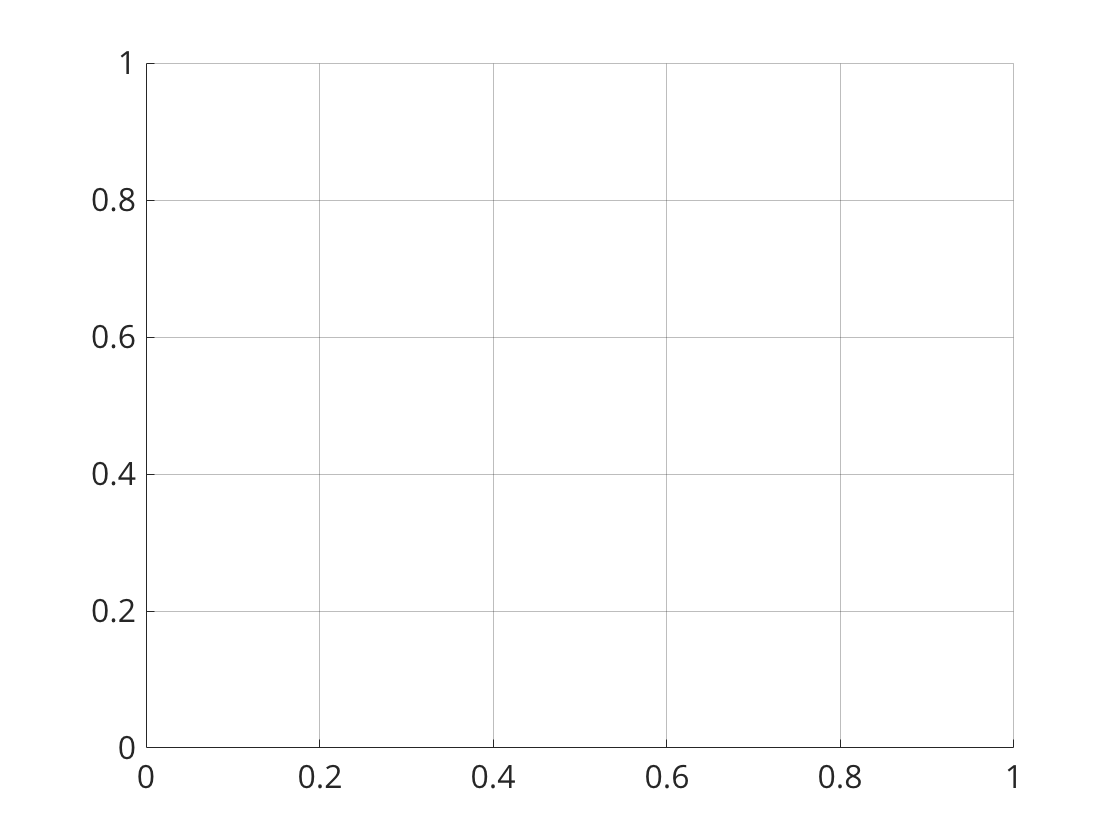

% Location parameter
mu = 0.54 ;

% Scale parameter (dispersion)
sigma0 = 0.092;

% Shape parameter (symmetry)
nu0 = -0.94;

% Lower bound
low = 0.07;

% Upper bound
high = 0.43;

%% Plot CDF 

figure();
hold on

plot(-z, glogc0(z, mu, sigma0, nu0, low, high));

Unrecognized function or variable 'z'.

set(gca( ), "xLim", [min(-z), max(-z)], "yLim", [0, high+0.05]);
xline(0, "lineWidth", 2);
xlabel("Expected value of NGA to GDP ratio");
ylabel("Expected loss % PA");
title("Baseline parameterization");


## Alternative parameterization (used in the model): `glogc1`

% Value of the function at 0
q0 = 0.00125;

% Scale parameter (dispersion)
sigma1 = 0.01;

% Shape parameter (symmetry)
nu1 = -1.2;

% Lower bound
rellow = -0.00125;

% Upper bound
relhigh = 0.1;

figure();
hold on;
plot(-z, glogc1(z, q0, sigma1, nu1, rellow, relhigh), "color", "red");

Unrecognized function or variable 'z'.

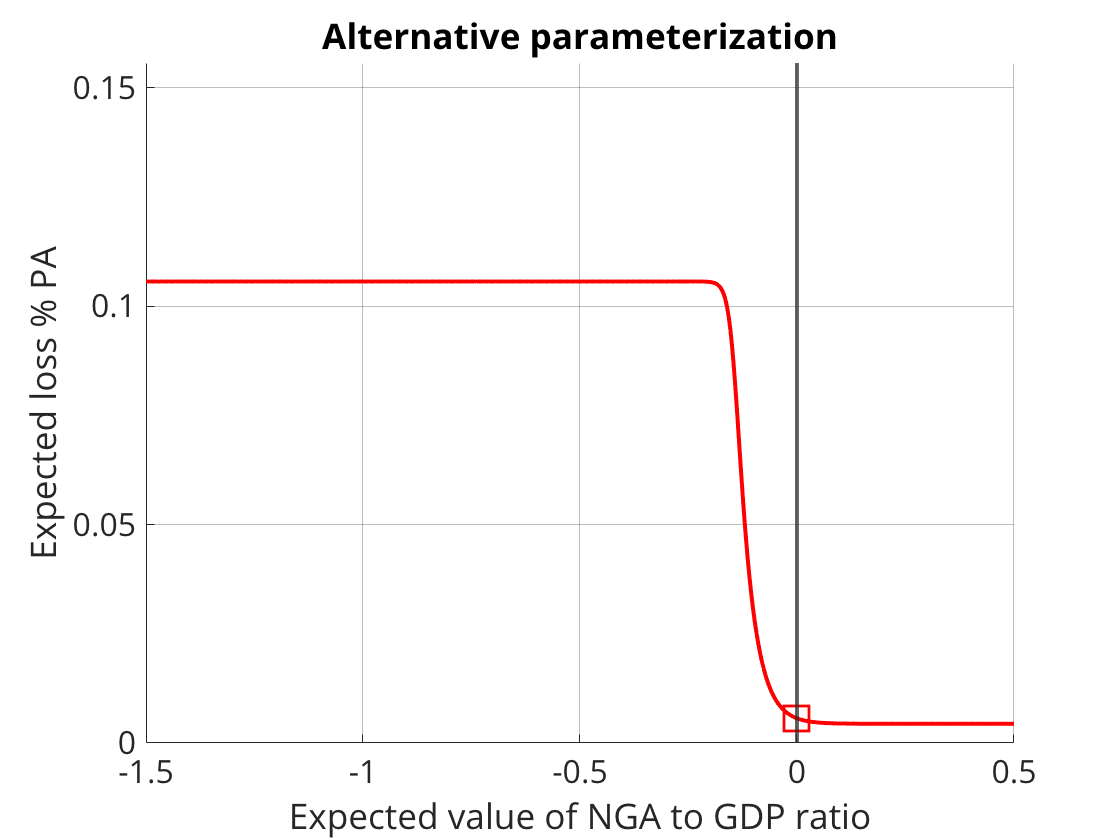

plot(0, q0, "color", "red", "lineStyle", "none", "marker", "s", "markerSize", 16);
set(gca( ), "xLim", [min(-z), max(-z)], "yLim", [0, q0+relhigh+0.05]);
xline(0, "lineWidth", 2);
xlabel("Expected value of NGA to GDP ratio");
ylabel("Expected loss % PA");
title("Alternative parameterization");